# assignment 3

## params

% init
close all;
clc;
% parameter
curb_weight = 1000; % kg
sprung_mass_w = 900;% kg
unsprung_mass = 25; % kg each wheel
Izz = 2000; % kg-m^2
Ixx = 750; % kg-m^2
wheel_base = 2.6; % m
a = 1.2; % m
b = wheel_base - a; % m
h_cg = 0.6; % m
h_cg_unsprung = 0.7; % m
h_roll_center = 0.2; %m

% tire
tire_C = 25000; % N/rad
vertcal_stiffness = 150000; % N/m
cf_absorb = 800; % N/m/s
cr_absorb = 1000; % N/m/s
dist_spring = 1.3; % m
dist_absorb = 1.3; % mor
installation_factor = 1;

## Part 1

### Q1

Q1.1.a

% omega
omega_f = 1.1*2*pi; % hz -> rad/s

mf = sprung_mass_w*a/2/wheel_base

mf = 207.6923

kf = omega_f^2*mf

kf = 9.9212e+03

Q1.1.b

% omega
omega_r = 1.3*2*pi; % hz -> rad/s
mr = sprung_mass_w*b/2/wheel_base

mr = 242.3077

kr = omega_r^2*mr

kr = 1.6166e+04

Q1.2.a

k = 1/(1/kf+1/vertcal_stiffness)

k = 9.3057e+03

dp_ratio = cf_absorb/2/sqrt(k*mf)

dp_ratio = 0.2877

c1 = 2*dp_ratio*omega_f

c1 = 3.9772

Q1.2.b

magnitude = 0.1; % m
l_wave = 1.2; % m
vel = 5/3.6; % km/h -> m/s

% 1 DOF
% with frequency omega_f


% with frequency omega_r


### Q2

Q2.1

k_us = -(curb_weight*a*tire_C-curb_weight*b*tire_C)/(wheel_base*tire_C*tire_C)

k_us = 0.0031

Q2.2

velocity=0:0.2:200;
u=velocity*3.6;
yaw_v_gain = u./(wheel_base+k_us*u.^2)

yaw_v_gain =          0    0.2768    0.5525    0.8262    1.0969    1.3637    1.6256    1.8819    2.1317    2.3743    2.6092    2.8357    3.0533    3.2618    3.4608    3.6500    3.8294    3.9987    4.1581    4.3075    4.4471    4.5771    4.6975    4.8086    4.9108    5.0043    5.0893    5.1664    5.2356    5.2975    5.3524    5.4006    5.4425    5.4784    5.5087    5.5336    5.5536    5.5690    5.5799    5.5868    5.5899    5.5895    5.5858    5.5791    5.5696    5.5574    5.5429    5.5262    5.5075    5.4870


yaw_v_gain_neutral = u./(wheel_base)

yaw_v_gain_neutral =          0    0.2769    0.5538    0.8308    1.1077    1.3846    1.6615    1.9385    2.2154    2.4923    2.7692    3.0462    3.3231    3.6000    3.8769    4.1538    4.4308    4.7077    4.9846    5.2615    5.5385    5.8154    6.0923    6.3692    6.6462    6.9231    7.2000    7.4769    7.7538    8.0308    8.3077    8.5846    8.8615    9.1385    9.4154    9.6923    9.9692   10.2462   10.5231   10.8000   11.0769   11.3538   11.6308   11.9077   12.1846   12.4615   12.7385   13.0154   13.2923   13.5692


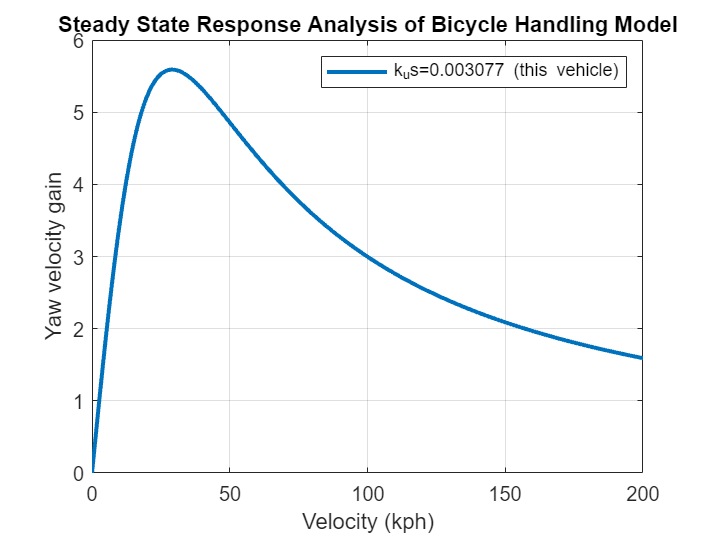


% plot
plot(u,yaw_v_gain,'LineWidth',2);

title("Steady State Response Analysis of Bicycle Handling Model");
legend('k_us=0.003077 (this vehicle)');
xlabel("Velocity (kph)");
ylabel("Yaw velocity gain");
xlim([0 200])
ylim([0 6])
grid on;
hold off

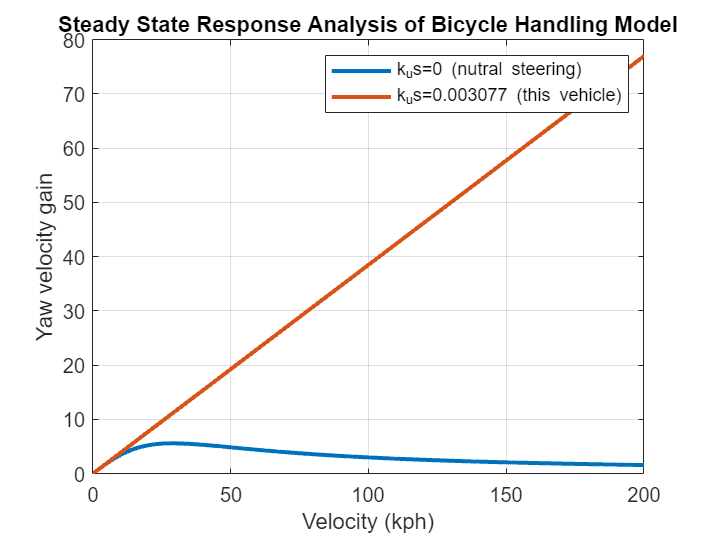


% double plot
plot(u,yaw_v_gain,'LineWidth',2);
hold on;
plot(u,yaw_v_gain_neutral,'LineWidth',2);

title("Steady State Response Analysis of Bicycle Handling Model");
legend('k_us=0 (nutral steering)','k_us=0.003077 (this vehicle)');
xlabel("Velocity (kph)");
ylabel("Yaw velocity gain");
xlim([0 200])
ylim([0 80])
grid on;
hold off